dirname = 'C:\Users\nsah01\Downloads\VisTexColor40_2023\'

dirname = 'C:\Users\nsah01\Downloads\VisTexColor40_2023\'

nlevels = 3

nlevels = 3

nsubs = 16

nsubs = 16


color=0;
[rr,r, rs, ormax]= CBIR_Simple(dirname,nlevels,nsubs,color)

rr =      1     5   154    63     5     2    56    55     2     8    81    60     2    75   105    43     1    77     5   268   173     2   238    72     2   175   205   140   183   120    32   422     1     8     3     9     3    18    21    29     3    31    29    80     4    46    37    18     1    28
     9     1    69    24    15     9    26    17     6     2    32    21    10    45    63    14    26     1     6    56     6    18    24     8    17    18     7    17    49     4     3   200     7     1     4    50     4     2    10     5    16    22    15    21     8    75    32     8    11     1
   105    52     1    21   254    72    23    13   169    56     7    16   114    20    23    34     5    12     1   182    59     4   158    24     4   125   103    95   144    26     5   358     2     3     1    24     2    12    26    25     8    33    28    67     6    82    41    11    31     4
    26    19    15     1   122    21     4     4    49    15     4     2    25    10    18  

r = 62.7637

rs =    44.9219   44.1406   62.8906   39.4531   66.0156   60.5469   42.1875   92.5781   83.5938   63.6719   89.0625   60.1562   54.6875   91.7969   75.0000   78.9062   96.4844   41.7969   64.0625   76.1719   75.0000   55.4688   46.4844   21.0938   55.0781   66.7969   50.0000   74.2188   95.3125   57.0312   66.0156   43.7500   68.7500   42.1875   33.5938   48.0469   88.6719   84.7656   19.9219   90.2344


ormax = 91.3062

color = 2;
[rr_color,r_color, rs_color, ormax_color]= CBIR_Simple(dirname,nlevels,nsubs,color)

rr_color =      1     5    16    47     2     2     7    35     6     2    20    53     5    61    54    59     1    19     7   131    63     2   107    11     3    71   146    10    68    35    15   245     1    13    18    23     2    18    31    18     5    19    32    60    13    21     4    17     1     3
     7     1     5    13    14     8     5    14    57     7     6    15    28    89    34    17    15     1     4    11     6    20     8     9    93     9     7    12    35     2     5    25     7     1     2     8     7     3     4     2     6     4     6     8     2     4     2     2     2     1
    22     8     1    16    56    21     3     5    63    21     3    19    30    39     5    28     5     4     1    18    13     4    17     5    28    15    27     6    40     6     2    97    22     3     1    16    23     5     2     5    13    10     7    11     5     5     7     3     7     4
    88    30    34     1   105    83    34     9   188   105    21     2   127   147  

r_color = 76.6504

rs_color =    38.6719   63.6719   73.0469   74.2188   62.1094   79.2969   78.1250   96.4844   96.4844   60.1562   96.4844   82.4219   94.9219   95.7031   91.7969   98.8281   93.7500   72.2656   94.1406   98.8281   60.5469   49.6094   62.8906   68.7500   87.1094   62.1094   65.2344   64.0625   94.5312   82.8125   83.2031   46.4844   60.9375   63.6719   51.1719   85.1562   99.6094   98.0469   39.0625   99.6094


ormax_color = 94.8114

disp('Performances pour les images en couleur :');

Performances pour les images en couleur :


disp(['Taux de reconnaissance global : ', num2str(r_color), '%']);

Taux de reconnaissance global : 76.6504%



disp('Performances pour les images en niveau de gris :');

Performances pour les images en niveau de gris :


disp(['Taux de reconnaissance global : ', num2str(r), '%']);

Taux de reconnaissance global : 62.7637%


color=0

color = 0


% Entrez le fichier spécifique pour la recherche
queryFile = 'C:\Users\nsah01\Downloads\VisTexColor40_2023\Fabric.0000.12.tif'

queryFile = 'C:\Users\nsah01\Downloads\VisTexColor40_2023\Fabric.0000.12.tif'


% Chargez l'image de requête
queryImage = imread(queryFile);

% Extrayez les caractéristiques de l'image de requête
queryFeatures = wavefeat_asd('C:\Users\nsah01\Downloads\VisTexColor40_2023\Fabric.0000.12.tif', nlevels);

% Chargez les caractéristiques de la base de données
databaseFeatures = wavefeat_asd_INDEX(dirname, nlevels,color);

% Classez les images de la base de données en fonction de la similarité avec l'image de requête
ranking = ranked(databaseFeatures, nsubs);

% Affichez le classement
disp('Classement des images de la base de données en fonction de la similarité :');

Classement des images de la base de données en fonction de la similarité :


disp(ranking);

     1     5   154    63     5     2    56    55     2     8    81    60     2    75   105    43     1    77     5   268   173     2   238    72     2   175   205   140   183   120    32   422     1     8     3     9     3    18    21    29     3    31    29    80     4    46    37    18     1    28    78    19    49    57    56    19    53     6    80    38   102     2    25    21     1     5     3     6    97     2    30     7     6    16     9     6   185     9     9     6     1    41    15    11    64     9    11    11    11    13   111    20    10    21    14    71     1     2   113    61   106   101   100    66   119     8    73     2   122    32     2    72     1    12    12    15     9    12    13    12    22    15    17    12    24    13    12     9     1     4    10   198     5     5    11    30     3     3     7    32     2     3     4    12     1     4    27    37     3    10    30    35    13    26    42    52    42    55    47    89     1     8     9    13    13    14    


% Évaluez la performance du CBIR
[recognitionRate, avgRecognitionRate, operatingRecognitionRate] = evalir(ranking);

% Affichez les résultats
disp(['Taux de reconnaissance global : ', num2str(recognitionRate), '%']);

Taux de reconnaissance global : 62.7637%


disp(['Taux de reconnaissance moyen par classe : ', num2str(avgRecognitionRate), '%']);

Taux de reconnaissance moyen par classe : 44.9219      44.1406      62.8906      39.4531      66.0156      60.5469      42.1875      92.5781      83.5938      63.6719      89.0625      60.1562      54.6875      91.7969           75      78.9062      96.4844      41.7969      64.0625      76.1719           75      55.4688      46.4844      21.0938      55.0781      66.7969           50      74.2188      95.3125      57.0312      66.0156        43.75        68.75      42.1875      33.5938      48.0469      88.6719      84.7656      19.9219      90.2344%


disp(['Taux de reconnaissance opérationnel : ', num2str(operatingRecognitionRate), '%']);

Taux de reconnaissance opérationnel : 91.3062%


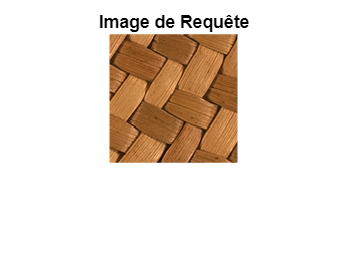


% Visualisez les images dans une figure
figure;

% Affichez l'image de requête
imshow(queryImage);
title('Image de Requête');


% Affichez les images de la base de données les plus similaires
for i = 1:nsubs
    % Obtenez le chemin de l'image à partir du classement
    imagePath = fullfile(dirname, ranking(i).name);
    
    % Chargez l'image
    similarImage = imread(imagePath);
    
    % Affichez l'image dans la figure
    subplot(3, nsubs + 1, i + 1);
    imshow(similarImage);
    title(['Similaire #', num2str(i)]);
end

Dot indexing is not supported for variables of this type.


% Évaluez la performance du CBIR
[recognitionRate, avgRecognitionRate, operatingRecognitionRate] = evalir(ranking);

% Affichez les résultats
disp(['Taux de reconnaissance global : ', num2str(recognitionRate), '%']);
disp(['Taux de reconnaissance moyen par classe : ', num2str(avgRecognitionRate), '%']);
disp(['Taux de reconnaissance opérationnel : ', num2str(operatingRecognitionRate), '%']);